P = "test_img/pepper.ascii.pgm";
% P = "test_img/apollonian_gasket.ascii.pgm";
Test_Image = imread(fullfile(P));
% P = "test_img/Image.txt"
% Test_Image = readmatrix(P);

P = "test_img/Compressed_Image.txt";
Compressed_Image = readmatrix(P);
% P = "test_img/Compressed_Image.pgm";
% Compressed_Image = imread(fullfile(P),"pgm");

[row, col] = size(Test_Image);
cell_rows = ones(row/8,1).*8;
cell_cols = ones(col/8,1).*8;
cell = mat2cell(Test_Image, cell_rows, cell_cols);
cell = cellfun(@(x) dct2(x), cell, 'un', 0);
comp = cell2mat(cell);
cell = cellfun(@(x) idct2(x), cell, 'un', 0);
Verified_Image = cell2mat(cell);
Verified_Image = abs(round(Verified_Image))

Verified_Image =     26    47    49    43    44    44    46    41    43    42    43    43    42    42    41    39    44    39    42    45    46    42    39    39    36    39    37    37    35    41    37    35    33    34    33    37    36    33    35    33    37    60    88   104   109   111   108    98    51    24
    48    97    94    87    88    88    95    82    88    83    85    93    85    85    87    81    85    84    81    88    85    83    83    79    83    79    87    80    87    79    78    75    78    70    70    72    74    75    71    71    66    97   151   198   223   227   227   221   183    96
    47   102    95    91    88    86    94    82    94    95    77    81    82    84    84    80    81    82    86    84    84    83    75    92    81    96    80    84    87    83    84    83    78    84    82    80    75    74    68    66    70    66   108   166   205   220   230   230   223   198
    45    88    88    88    86    94    95    92    84    92    86    86    87  

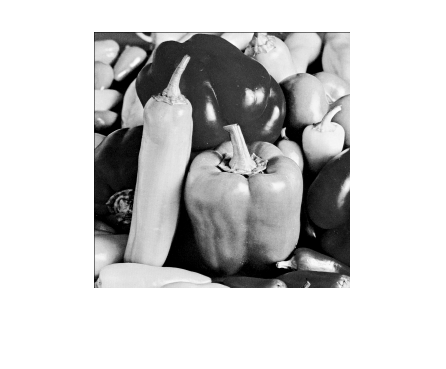

imshow((uint8(Verified_Image)));

% imwrite(uint8(Verified_Image), 'test_img/verified.pgm');

[row, col] = size(Compressed_Image);
cell_rows = ones(row/8,1).*8;
cell_cols = ones(col/8,1).*8;
Compressed_Image = Compressed_Image/(2^3);
cell = mat2cell(Compressed_Image, cell_rows, cell_cols);
cell = cellfun(@(x) idct2(x), cell, 'un', 0);
Decompressed_Image = cell2mat(cell);
Decompressed_Image = abs(round(Decompressed_Image))

Decompressed_Image =     25    47    49    43    44    44    46    41    42    42    43    43    42    42    41    39    43    39    42    45    46    42    39    39    35    39    37    37    35    41    37    35    32    34    33    37    36    33    35    33    36    60    88   104   109   111   108    98    50    24
    48    97    94    87    88    88    95    82    88    83    85    93    85    85    87    81    85    84    81    88    85    83    83    79    83    79    87    80    87    79    78    75    78    70    70    72    74    75    71    71    66    97   151   198   223   227   227   221   183    96
    46   102    95    91    88    86    94    82    94    95    77    81    82    84    84    80    81    82    86    84    84    83    75    92    81    96    80    84    87    83    84    83    78    84    82    80    75    74    68    66    69    66   108   166   205   220   230   230   222   198
    45    88    88    88    86    94    95    92    84    92    86    86    

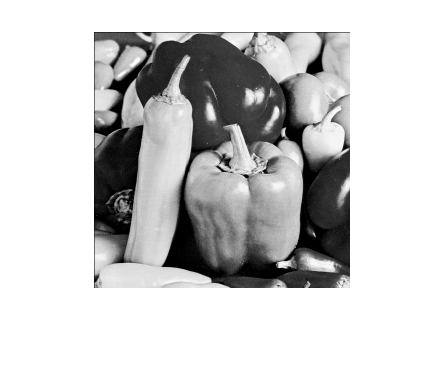

% Decompressed_Image = min(max(Decompressed_Image,255),0)
imshow((uint8(Decompressed_Image)));

imwrite(uint8(Decompressed_Image), 'test_img/Decompressed_Image.pgm', 'Encoding', 'ASCII');


Psimax = 255;
sigma2e = mean(mean((Decompressed_Image - Verified_Image).^2));
PSNR = 10*log10((Psimax^2)/sigma2e)

PSNR = 64.7422